clc;clear;
syms epsilon l d theta_1 k
p = 2*l*sin(epsilon/2)

$$p = 2\,l\,\sin\left(\frac{\epsilon }{2}\right)$$

m = sqrt(p^2+d^2-2*p*d*cos((pi-epsilon)/2+theta_1))

$$m = \sqrt{d^{2}-4\,\cos\left(\theta_{1}-\frac{\epsilon }{2}+\frac{\pi }{2}\right)\,d\,l\,\sin\left(\frac{\epsilon }{2}\right)+4\,l^{2}\,{\sin\left(\frac{\epsilon }{2}\right)}^{2}}$$

x = m-d;
% x = subs(x,l,2.54*2*1e-2)
% x = subs(x,d,0.1)
% x = subs(x,theta_1,pi/6)
theta_L = asin(sin((pi-epsilon)/2+theta_1)*p/m)

$$theta\_L = \mathrm{asin}\left(\frac{2\,l\,\sin\left(\frac{\epsilon }{2}\right)\,\sin\left(\theta_{1}-\frac{\epsilon }{2}+\frac{\pi }{2}\right)}{\sqrt{d^{2}-4\,\cos\left(\theta_{1}-\frac{\epsilon }{2}+\frac{\pi }{2}\right)\,d\,l\,\sin\left(\frac{\epsilon }{2}\right)+4\,l^{2}\,{\sin\left(\frac{\epsilon }{2}\right)}^{2}}}\right)$$

h = l*sin(theta_1+theta_L);
T = h*k*x

$$T = \begin{array}{l} -k\,l\,\sin\left(\theta_{1}+\mathrm{asin}\left(\frac{2\,l\,\sin\left(\frac{\epsilon }{2}\right)\,\sin\left(\theta_{1}-\frac{\epsilon }{2}+\frac{\pi }{2}\right)}{\sigma_{1}}\right)\right)\,\left(d-\sigma_{1}\right)\\ \mathrm{where}\\ \sigma_{1}=\sqrt{d^{2}-4\,\cos\left(\theta_{1}-\frac{\epsilon }{2}+\frac{\pi }{2}\right)\,d\,l\,\sin\left(\frac{\epsilon }{2}\right)+4\,l^{2}\,{\sin\left(\frac{\epsilon }{2}\right)}^{2}} \end{array}$$

T_epsilon = subs(T,[l,d,k],[2.54*2*1e-2,0.12,4000])

$$T\_epsilon = \begin{array}{l} \frac{1016\,\sin\left(\theta_{1}+\mathrm{asin}\left(\frac{127\,\sin\left(\frac{\epsilon }{2}\right)\,\sin\left(\theta_{1}-\frac{\epsilon }{2}+\frac{\pi }{2}\right)}{1250\,\sigma_{1}}\right)\right)\,\left(\sigma_{1}-\frac{3}{25}\right)}{5}\\ \mathrm{where}\\ \sigma_{1}=\sqrt{\frac{16129\,{\sin\left(\frac{\epsilon }{2}\right)}^{2}}{1562500}-\frac{381\,\cos\left(\theta_{1}-\frac{\epsilon }{2}+\frac{\pi }{2}\right)\,\sin\left(\frac{\epsilon }{2}\right)}{15625}+\frac{9}{625}} \end{array}$$

theta_L = double(subs(theta_L,[l,d,theta_1,epsilon],[2.54*2*1e-2,0.15,0.4,0.1]))

theta_L = 0.0314

h = double(subs(h,[l,d,theta_1,epsilon],[2.54*2*1e-2,0.05,0,0.1]))

h = 0.0052

T_list = [];
klist =[];
ep = linspace(-0.1,0.1,101);
t1 = linspace(pi/2-0.4,pi/2,41);
for l = 1:41
    T_list = [];
    %T_ep = subs(T_epsilon,theta_1,t1(l))
    for i = 1:101
        T_ep = double(subs(T_epsilon,[theta_1,epsilon],[t1(l),ep(i)]));
        T_list = [T_list,T_ep];
    end
    %plot(ep,T_list)
    kc= polyfit(ep,T_list,1);
    klist = [klist,kc(1)];
end
%plot(ep,T_list)
%polyfit(ep,T_list,1)

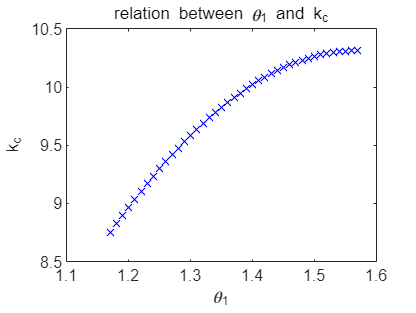

plot(t1,klist,'bx')
title('relation between \theta_1 and k_c')
xlabel('\theta_1')
ylabel('k_c')

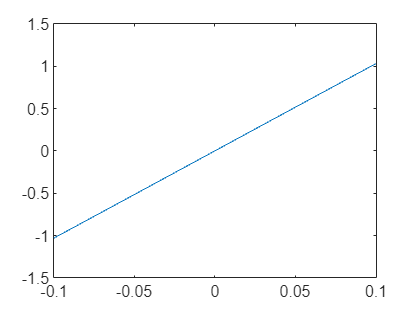

figure
plot(ep,T_list)

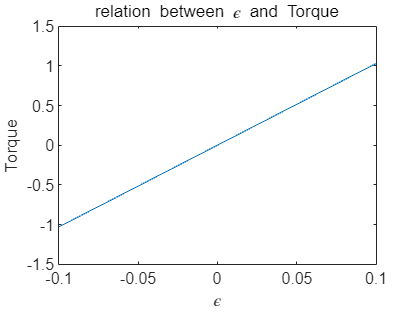


title('relation between \epsilon and Torque')
xlabel('\epsilon')
ylabel('Torque')